# trajectory evaluation ros2 bag

bag = ros2bagreader("lattice_calibration_data/15x15x15/trial4/lattice_data_1");

% get the transformation tree
start_time = bag.StartTime;
end_time = bag.EndTime;

t = start_time:0.01:end_time;
t= t';
n_msgs = size(t,1);

for i = 1:n_msgs
    if canTransform(bag,"left_tool0","world",t(i))
        break;
    end
end

start_index = i;

if i > 1
    t(1:start_index-1) = [];
end

n_msgs = size(t,1);

i = 1;
while true
    if ~(canTransform(bag,"left_tool0","world",t(i)))        
        break;
    end
    i=i+1;
    if i > n_msgs
        break;
    end
end
end_index = i;

if(end_index<=n_msgs)
    t(end_index:end) = [];
end

start_time = t(1);
end_time = t(end);

n_msgs = size(t,1);
z = zeros(n_msgs,1,"double");

for i=1:n_msgs
    transform = getTransform(bag,"left_tool0","world",t(i));
    z(i) = transform.transform.translation.z;
end

z = -z + z(1); % invert the function

## F(z) plot

f_bag = select(bag,"Topic","/nano_17_proxy/ft");

f_msgs = readMessages(f_bag);

for j = 1:n_msgs
    if f_msgs{1}.data(1)<t(j)
        break
    end
end

if j>1
    z(1:j-1) = [];
    t(1:j-1) = [];
end

n_msgs = size(t,1);

for j = 1:n_msgs
    if f_msgs{end}.data(1) < t(j)
        break
    end
end

if j < n_msgs
    t(j:n_msgs) = [];
    z(j:n_msgs) = [];
end

n_msgs = size(t,1);

fz = zeros(n_msgs,1,"double");
it = 1;
for i=1:n_msgs
    current_time = t(i);
    while f_msgs{it}.data(1) < current_time
        it = it+1;
    end
    forward_timestamp = f_msgs{it}.data(1);
    backward_timestamp = f_msgs{it-1}.data(1);
    forward_fz = f_msgs{it}.data(4);
    backward_fz = f_msgs{it-1}.data(4);
    slope = (forward_fz - backward_fz)/(forward_timestamp-backward_timestamp);
    fz(i) = backward_fz + slope * (current_time - backward_timestamp);
end

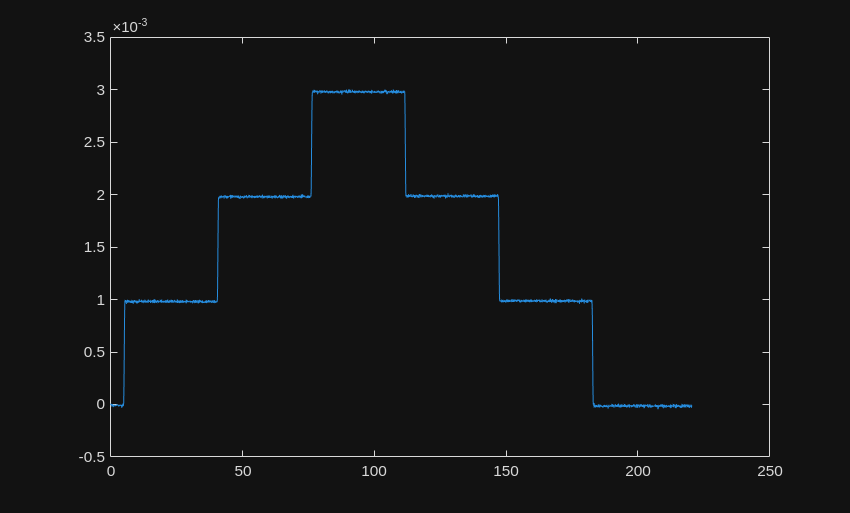

t_biased = t - t(1);
plot(t_biased,z);

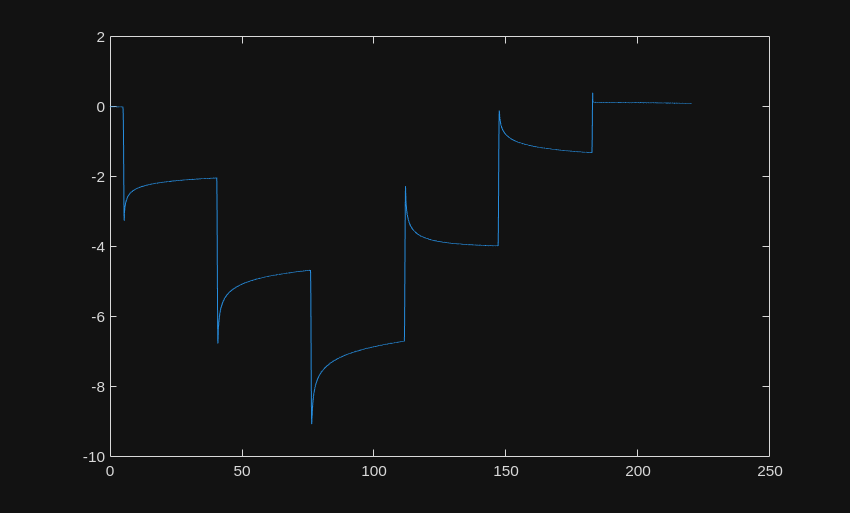

plot(t_biased,fz);